# PROF. AMBROSINO R.___ESAME___11/03/2026___SALVATORE_RAIOLA_DE6000008

clear; close all; clc;

## 0)  DEFINIZIONI

#### Variabili simboliche

syms q1 q2 dq1 dq2 ddq1 ddq2 u1 u2 w real

#### Parametri

m1 = 1.0;
m2 = 1.2;
k1 = 20;
k2 = 25;
c1 = 1;
c2 = 1.2;
k = 15;
c = 0.8;
k3 = 40;

#### I-S-U

% Ingresso
u = [u1;
     u2];

% Stato
x = [q1;
     q2;
     dq1;
     dq2];

% Uscita
y = [q1;
     q2];

#### Modello Dinamico

% Equazioni del sistema
eq_1_sym = -k1*q1 - c1*dq1 + k*(q2-q1) + k3*(q2-q1)^3 + c*(dq2-dq1) + u1 == m1*ddq1;
eq_2_sym = -k2*q2 - c2*dq2 - k*(q2-q1) - k3*(q2-q1)^3 - c*(dq2-dq1) + u2 == m2*ddq2;

eqs_sym = [eq_1_sym;
           eq_2_sym];

eqs = solve(eqs_sym, [ddq1, ddq2], "ReturnConditions", true);

%dx/dt
f = [dq1;
     dq2;
     eqs.ddq1;
     eqs.ddq2];

%y
g = y;

% Matrici Simboliche
A_sym = jacobian(f, x);
B_sym = jacobian(f, u);
C_sym = jacobian(g, x);
D_sym = jacobian(g, u);

n = size(A_sym,1);
m = size(B_sym,2);

## 1)  PUNTI DI EQUILIBRIO E LINEARIZZAZIONE

### 1.1) Punti di equilibrio

eq_1_peql = subs(eq_1_sym, [dq1, dq2, ddq1, ddq2, u1, u2], [0, 0, 0, 0, 0, 0]) == 0;
eq_2_peql = subs(eq_2_sym, [dq1, dq2, ddq1, ddq2, u1, u2], [0, 0, 0, 0, 0, 0]) == 0;

eqs_peql = [eq_1_peql;
            eq_2_peql];

peql = solve(eqs_peql, [q1, q2], "ReturnConditions", true);

q1_eql = double(peql.q1);
q2_eql = double(peql.q2);

disp(table(q1_eql, q2_eql));

    q1_eql    q2_eql
    ______    ______

      0         0   



### 1.2)  Punto di equilibrio x* corrispondente a u1* = 1 N e u2* = -0.5 N

% Punto di lavoro
u1_star = 1;
u2_star = -0.5;

u_star = [u1_star;
          u2_star];

% Punto di equilibrio corrispondente
eq_1_star = subs(eq_1_sym, [dq1, dq2, ddq1, ddq2, u1, u2], [0, 0, 0, 0, u1_star, u2_star]) == 0;
eq_2_star = subs(eq_2_sym, [dq1, dq2, ddq1, ddq2, u1, u2], [0, 0, 0, 0, u1_star, u2_star]) == 0;

eqs_star = [eq_1_star;
            eq_2_star];

q_star = solve(eqs_star, [q1, q2], "ReturnConditions", true);

q1_star = double(q_star.q1);
q2_star = double(q_star.q2);

dq1_star = 0;
dq2_star = 0;

x_star = [q1_star;
          q2_star;
          0;
          0];

disp(table(q1_star, q2_star, dq1_star, dq2_star));

    q1_star      q2_star      dq1_star    dq2_star
    ________    __________    ________    ________

    0.027637    -0.0021097       0           0    



### 1.3)  Modello Linearizzato nell'intorno di x*

A = double(subs(A_sym, [x; u], [x_star; u_star]));
B = double(subs(B_sym, [x; u], [x_star; u_star]));
C = double(subs(C_sym, [x; u], [x_star; u_star]));
D = double(subs(D_sym, [x; u], [x_star; u_star]));

sys = ss(A, B, C, D)


sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  -35.11   15.11    -1.8     0.8
   x4   12.59  -33.42  0.6667  -1.667
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3       1       0
   x4       0  0.8333
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


### 1.4)  Controllabilità e Osservabilità

#### Controllabilità

if(rank(ctrb(A,B)) == n)
    disp('Il sistema linearizzato è completamente controllabile');
else
    disp('Il sistema linearizzato non è completamente controllabile');
end

Il sistema linearizzato è completamente controllabile


#### Osservabilità

if(rank(obsv(A,C)) == n)
    disp('Il sistema linearizzato è completamente osservabile');
else
    disp('Il sistema linearizzato non è completamente osservabile');
end

Il sistema linearizzato è completamente osservabile


## 2)  ASSEGNAMENTO AUTOVALORI

#### Specifiche

% Autovalori desiderati - con aggiunta di un delta per non far fallire il
% comando place
delta_eig = 0.0001;
eig_des = [-5, -5-delta_eig, -10, -10-delta_eig];

% Condizione iniziale
q1_0 = 0.1;
q2_0 = 0.3;

q0 = [q1_0;
      q2_0;
      0;
      0];

% Riferimento
q1_ref = 0.5;
q2_ref = 1;

q_ref = [q1_ref;
         q2_ref];

#### Sintesi Assegnamento Autovalori

K_EIG = place(A, B, eig_des)

K_EIG =    64.8948   15.1062   18.2001    0.8000
   15.1062  -10.1056    0.8000   10.0001


#### Compensazione del guadagno 

cl_sys = ss((A-B*K_EIG), B, C, D);
gain = dcgain(cl_sys);

N = pinv(gain)

N =   100.0010         0
         0   30.0006


C_eig = eye(n);
D_eig = zeros(n,m);

#### Verifica Simulazione

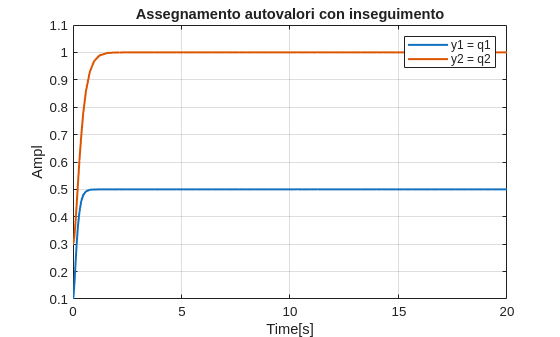

% Plot MATLAB
out = sim('Verifica_EIG_11032026.slx');
y1_eig = out.y1.Data;
y2_eig = out.y2.Data;
time = out.y1.Time;

figure
plot(time, y1_eig, "LineWidth", 1.5);
grid on
hold on 
plot(time, y2_eig, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = q1', 'y2 = q2');
title('Assegnamento autovalori con inseguimento');

**Lo schema Simulink è consultabile dal seguente link**

Schema Simulink:  [Verifica_EIG](matlab:open_system('Verifica_EIG_11032026.slx'))

## 3)  CONTROLLO LQR CON AZIONE INTEGRALE

#### Specifiche

% Tempo di Assestamento
Ts = 0.3;

% Riferimento su q1
% q1_ref = 0.5;  già definito nella sezione precedente 
q_ref_LQR = [q1_ref;
             0];

#### Sistema Aumentato

C_tot = [1, 0, 0, 0;
         0, 0, 0, 0;
         0, 0, 0, 0;
         0, 0, 0, 0];

D_tot = [D;
         zeros(2,2)];

C_LQR = [1, 0, 0, 0];

p_a = size(C_LQR,1);

alpha = 4/Ts;

A_aug = [A, zeros(n, p_a);
         -C_LQR, 0]

A_aug =          0         0    1.0000         0         0
         0         0         0    1.0000         0
  -35.1062   15.1062   -1.8000    0.8000         0
   12.5885  -33.4218    0.6667   -1.6667         0
   -1.0000         0         0         0         0


% A_aug = [A, zeros(n, p_a);
%         -C_LQR, 0]
n_aug = size(A_aug,1);

% Trasliamo lo spettro di A_aug cosi da rispettarre la specifica sul Ts
A_hat = A_aug - alpha*eye(n_aug);
eig(A_hat)

ans =  -13.3333 + 0.0000i
 -14.5665 + 6.8234i
 -14.5665 - 6.8234i
 -13.8335 + 4.4943i
 -13.8335 - 4.4943i



B_aug = [B;
         zeros(p_a,m)]

B_aug =          0         0
         0         0
    1.0000         0
         0    0.8333
         0         0


C_aug = [eye(n) zeros(n,1)];
D_aug = 0;

sys_aug = ss(A_aug,  B_aug, C_aug, D_aug);

#### Sintesi LQR

Q_bar = 1;
Q = C_aug'*Q_bar*C_aug + blkdiag(zeros(n,n), 100);
R = eye(m);

% Sintesi
[K_LQR, ~, ~] = lqr(sys_aug, Q, R)

K_LQR =     0.6811    0.2097    0.6332    0.2795   -9.3768
    0.1863    0.0908    0.2330    0.3637   -3.4749


K_LQR_x = K_LQR(:, 1:n)

K_LQR_x =     0.6811    0.2097    0.6332    0.2795
    0.1863    0.0908    0.2330    0.3637


K_LQR_i = K_LQR(:, n+1:end)

K_LQR_i =    -9.3768
   -3.4749


#### Verifica Simulazione

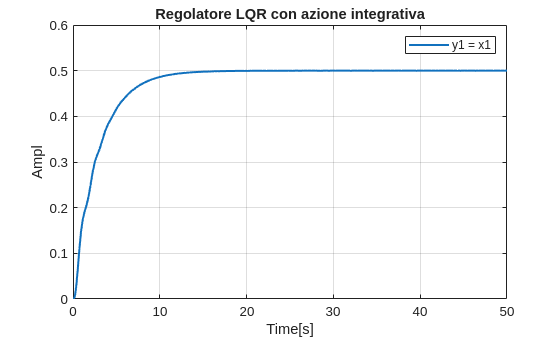

% Plot MATLAB
out = sim('Verifica_LQR_11032026.slx');
y1_lqr = out.y1.Data;
time = out.y1.Time;

figure
plot(time, y1_lqr, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1');
title('Regolatore LQR con azione integrativa');

**Lo schema Simulink è consultabile dal seguente link**

Schema Simulink:  [Verifica_LQR](matlab:open_system('Verifica_LQR_11032026.slx'))

## 4)  CONTROLLO H-INF

#### Specifiche

% --- Inseguimento ---

% Errore a regime massimo
e_ss = 0.005;

% Tempo di assestamento
Ta = 20;

% Sovraelongazione
zeta = 0.9;

Mp = 1*2*zeta;


% --- Reiezione disturbo ---

noise_atten_dB = 50;

wn = 20;

#### Sistema con Disturbo

eq_1_sym = -k1*q1 - c1*dq1 + k*(q2-q1) + k3*(q2-q1)^3 + c*(dq2-dq1) + u1 +w == m1*ddq1;

eqs = solve(eqs_sym, [ddq1, ddq2], "ReturnConditions", true);

u_w = [u;
       w];

%dz/dt
f_w = [dq1;
       dq2;
       eqs.ddq1;
       eqs.ddq2];

A_sym_w = jacobian(f_w, x);
B_sym_w = jacobian(f_w, u_w);
C_sym_w = jacobian(g, x);
D_sym_w = jacobian(g, u_w);

A_w = double(subs(A_sym_w, [x; u], [x_star; u_star]));
B_w = double(subs(B_sym_w, [x; u], [x_star; u_star]));
C_w = double(subs(C_sym_w, [x; u], [x_star; u_star]));
D_w = double(subs(D_sym_w, [x; u], [x_star; u_star]));

sys_w = ss(A_w, B_w, C_w, D_w)


sys_w =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  -35.11   15.11    -1.8     0.8
   x4   12.59  -33.42  0.6667  -1.667
 
  B = 
           u1      u2      u3
   x1       0       0       0
   x2       0       0       0
   x3       1       0       0
   x4       0  0.8333       0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
 
Continuous-time state-space model.


#### Funzioni di Peso

s = tf('s');

% Design Ws 
wc = 4/Ts;

Ws = (s/Mp + wc)/(s + e_ss*wc);
Ws_mimo = append([Ws, Ws])


Ws_mimo =
 
  From input 1 to output:
     s + 24
  ------------
  1.8 s + 0.12
 
  From input 2 to output:
     s + 24
  ------------
  1.8 s + 0.12
 
Continuous-time transfer function.


% Design Wt

Mr = 10^(noise_atten_dB/20);
At = 1e-5;

Wt = (s + At*wn)/(s/Mr + wn);
Wt_mimo = append([Wt, Wt])


Wt_mimo =
 
  From input 1 to output:
  316.2 s + 0.06325
  -----------------
      s + 6325
 
  From input 2 to output:
  316.2 s + 0.06325
  -----------------
      s + 6325
 
Continuous-time transfer function.


## CONTROLLO H-INF